clc; clear; close all;
darker_color = 0.5;
colors = [1 0 0; darker_color 0 0; 0 1 0; 0 darker_color 0; 0 0 1; 0 0 darker_color];

data_names = ["$a_x$", "$a_y$", "$a_z$", "$\omega_{x,b}$", "$\omega_{y,b}$", "$\omega_{z,b}$"];
data_names_cleaned = ["$a_{x, cleaned}$", "$a_{y, cleaned}$", "$a_{z, cleaned}$", "$\alpha_{x, cleaned}$", "$\alpha_{y, cleaned}$", "$\alpha_{z, cleaned}$"];

### Raw Accleration Data

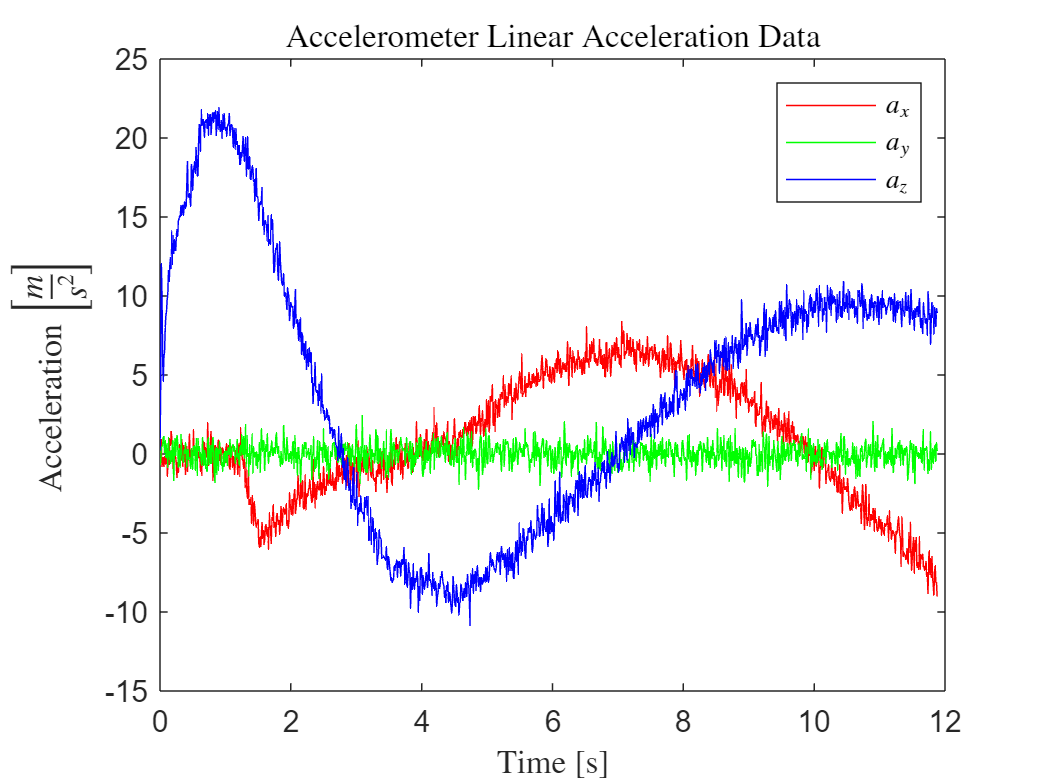

load("Acceleration Data.mat") % load noisy acceleration data
time = AccelerationData(:,1); % time vector

figure(1)
linear_x = AccelerationData(:,2);
linear_y = AccelerationData(:,3);
linear_z = AccelerationData(:,4);

plot(time, linear_x, Color=colors(1,:), DisplayName=data_names(1))
hold on
plot(time, linear_y, Color=colors(3,:), DisplayName=data_names(2))
plot(time, linear_z, Color=colors(5,:), DisplayName=data_names(3))
ylabel('Acceleration $\left[\frac{m}{s^2}\right]$', Interpreter='latex')
xlabel('Time [s]', Interpreter='latex')
title('Accelerometer Linear Acceleration Data', Interpreter='latex')
legend('location','NorthEast', Interpreter='latex')
hold off

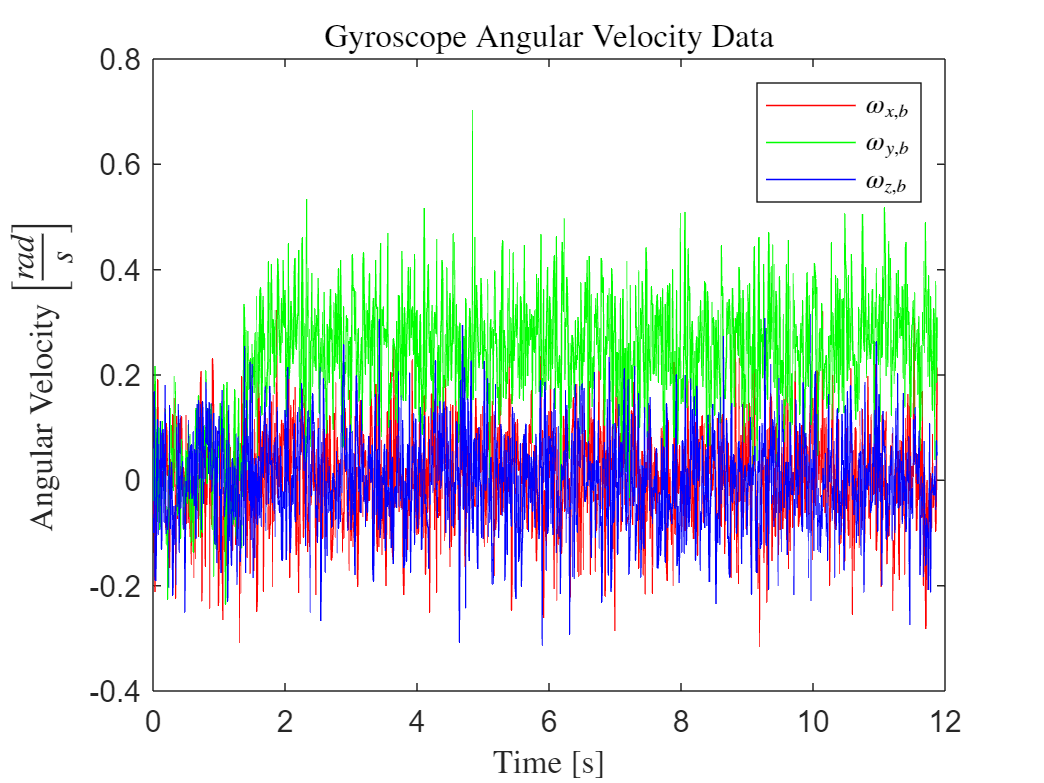


figure(2)
plot(time, AccelerationData(:,5), Color=colors(1,:), DisplayName=data_names(4))
hold on
plot(time, AccelerationData(:,6), Color=colors(3,:), DisplayName=data_names(5))
plot(time, AccelerationData(:,7), Color=colors(5,:), DisplayName=data_names(6))
ylabel('Angular Velocity $\left[\frac{rad}{s}\right]$', Interpreter='latex')
xlabel('Time [s]', Interpreter='latex')
title('Gyroscope Angular Velocity Data', Interpreter='latex')
legend('location','NorthEast', Interpreter='latex')
hold off

### Cleaned Data

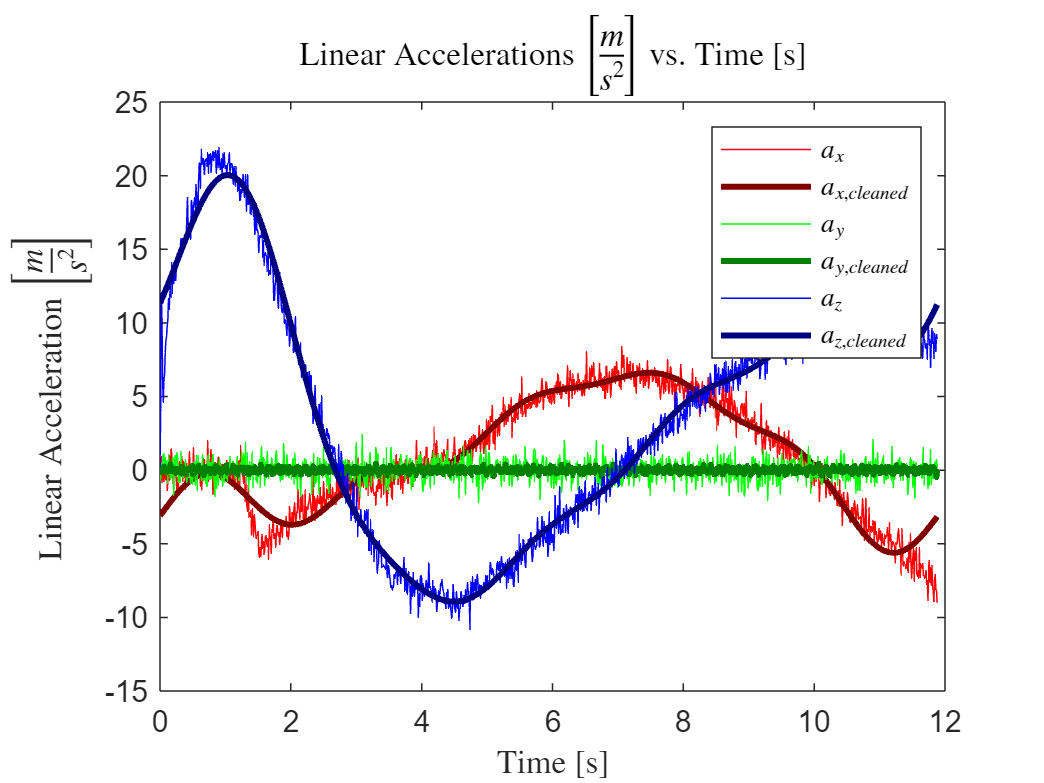

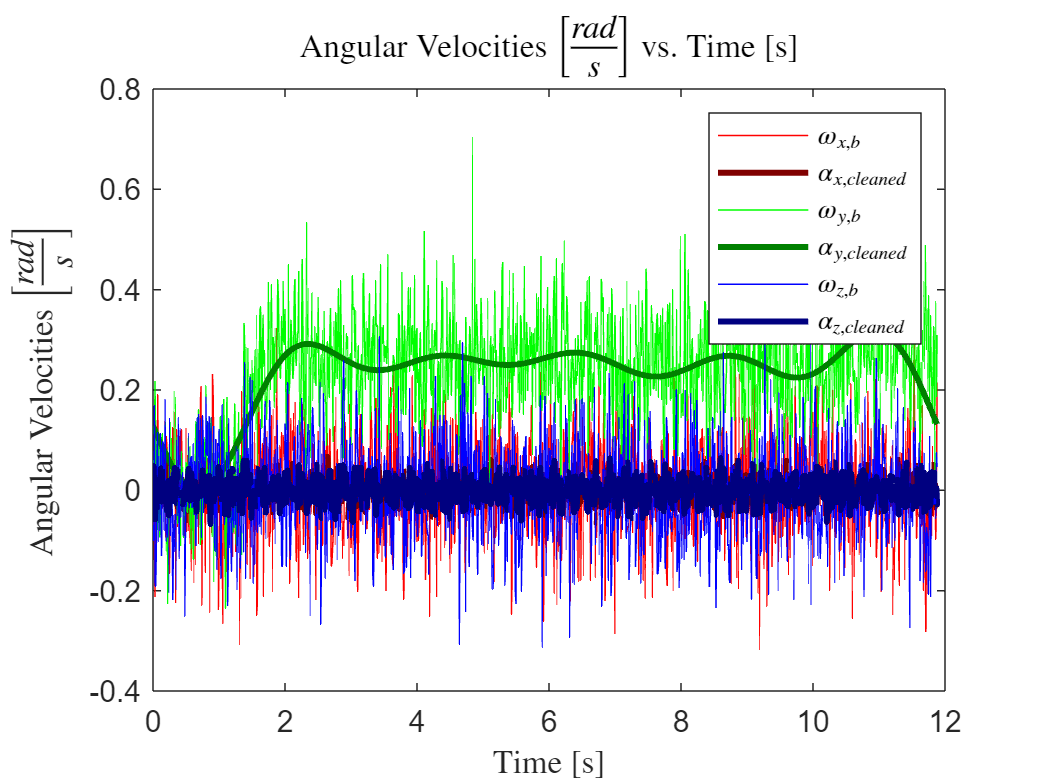

time = AccelerationData(:,1); % time vector, [s]
cleaned_Acceleration_Data = time;

Fs = find(time==1) - find(time==0); % sampling frequency, [Hz]
N = length(time); % number of samples
L = 1:floor(N/2); % vector to plot first half of FFT
freq = (0:N-1)*(Fs/N); % frequency vector (Hz)

% Clean (& Plot) Acceleration Data
[rows, cols] = size(AccelerationData);
for col = 2:7 % 1st column is time
    FFT = fft(AccelerationData(:,col), N); % fft of noisy signal
    PSD = FFT.*conj(FFT)/N; % PSD
    choice = 1; % decide whether to keep certain percentage of frequencies or certain count
    switch choice
        case 0
            percentage_to_keep = 2/100; % percentage of greatest amplitude frequencies to use
            indices = PSD>=min(maxk(PSD, floor(percentage_to_keep*length(PSD)))); % indices of most significant frequencies
        case 1
            number_to_keep = 11;
            indices = PSD>=min(maxk(PSD, number_to_keep));
    end
    FFT_cleaned = FFT.*indices;
    data_cleaned = ifft(FFT_cleaned);
    cleaned_Acceleration_Data = [cleaned_Acceleration_Data data_cleaned];
    if (col <= 4)
        figure(3)
        plot(time, AccelerationData(:, col), DisplayName=data_names(col-1))
        hold on
        plot(time, data_cleaned, LineWidth=2, DisplayName=data_names_cleaned(col-1))
        colororder(colors)
        title("Linear Accelerations $\left[\frac{m}{s^2}\right]$ vs. Time [s]", Interpreter="latex")
        legend(Interpreter="latex")
        xlabel("Time [s]", Interpreter="latex")
        ylabel("Linear Acceleration $\left[\frac{m}{s^2}\right]$", Interpreter="latex")
    else
        if (col == 5)
            hold off % turn "off" linear acceleration figure
        end
        figure(10)
        plot(time, AccelerationData(:, col), DisplayName=data_names(col-1))
        hold on
        plot(time, data_cleaned, LineWidth=2, DisplayName=data_names_cleaned(col-1))
        colororder(colors)
        title("Angular Velocities $\left[\frac{rad}{s}\right]$ vs. Time [s]", Interpreter="latex")
        legend(Interpreter="latex")
        xlabel("Time [s]", Interpreter="latex")
        ylabel("Angular Velocities $\left[\frac{rad}{s}\right]$", Interpreter="latex")
    end
end


save("Cleaned Acceleration Data", "cleaned_Acceleration_Data")